# LLR-Based Bit Vector Classification Using Probability Analysis

**Author:** Roberto Câmara (camara2k@gmail.com/ camara@ime.eb.br)

**Date:** Oct/2024

**Function Description:** This function computes the reliability of the canceled symbols according to a probabilitity cancellation criterion. 

**Key Features:**

- Based on the approach from **DOI:** [10.1109/MILCOM.2004.1494998](https://doi.org/10.1109/MILCOM.2004.1494998)

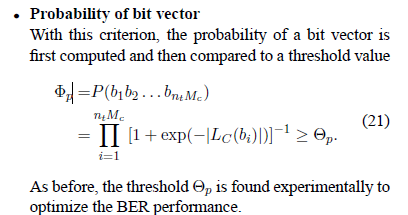

**Input:**

- ** sys: **struct of the system parameters `(n_tx, n_rx, Nc, M_ORD, sigma_n2_mW, PWR, PacketDataLength).`

- ** LLR:** the Log-Likelihood Ratio (LLR) value to be analyzed (can be `La, Lc `or` Ld`).

- ** symbolsErrors: **symbols that were  wrongly decoded. (obtained by the function `symbolsCompare`).

**Output:**

- **LLR_set_error**: Returns a vector containing only the incorrect LLRs sets values, with the correct ones fixed to zero.

- **LLR_set_correct**: Returns a vector containing only the correct LLRs sets  values, with the incorrect ones fixed to zero.

- **LLR_set_symb**: Returns the positions where the LLR values are correct.

function [LLR_set_symb,LLR_set_error,LLR_set_correct] = computeLLRProbability(sys, LLR,symbolsErrors)


Labs = real(LLR);
Labs_vec = reshape(Labs',1,512*(sys.n_tx));
% group the LLR of the bits acording to the modulation order.
Labs_aux = reshape(Labs_vec',sys.M_ORD,512*(sys.n_tx/sys.M_ORD));
aux = 1./(1+exp(-abs(Labs_aux)));

LLR_set_aux = 1;
for i = 1:sys.M_ORD
    LLR_set_aux = LLR_set_aux.*aux(i,:);
end

LLR_set_aux = reshape(LLR_set_aux,256,(sys.n_tx))';
LLR_set_symb = 1;
for i = 1:sys.n_tx
    LLR_set_symb = LLR_set_symb.*LLR_set_aux(i,:);
end

vector_errors = sum(symbolsErrors)>0;
LLR_set_error = LLR_set_symb.*vector_errors;
LLR_set_correct = LLR_set_symb.*(~vector_errors);
end